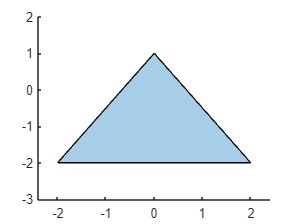

path_verts =polyshape([-2,2,0],[-2,-2,1]);
plot(path_verts);

verts = [[-2,2,0];[-2,-2,1]]';
line_int(verts,@(x,y) -y/2, @(x,y) x/2)

ans = 0

line_int(verts,@(x,y) -y/2, @(x,y) x/2)

ans = 0



area(path_verts)

ans = 6

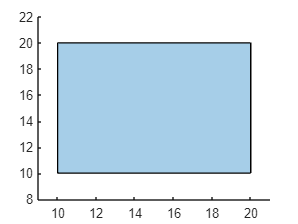

quad_vertex = [10 10; 20 10; 20 20; 10 20];
plot(polyshape(quad_vertex(:,1),quad_vertex(:,2)))

line_int(quad_vertex,@(x,y) -0.5*y.^2, @(x,y) 0*x)

ans = 0

centroid(polyshape(quad_vertex(:,1),quad_vertex(:,2)))

ans = 15

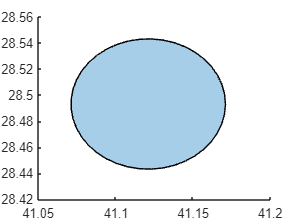

polyg = bots(3).verts_unc;
polg = polyshape(polyg(1,:),polyg(2,:));
plot(polg)

centroid(polg)

ans = 41.1211

line_int(polyg,@(x,y) 0*x, @(x,y) 0.5.*x.^2)/line_int(polyg,@(x,y) 0*x, @(x,y) x)

ans = 41.1211

poly2ccw(polyg(1,:),polyg(2,:))

ans =    41.1705   41.1688   41.1659   41.1620   41.1572   41.1514   41.1450   41.1380   41.1307   41.1230   41.1154   41.1079   41.1007   41.0940   41.0879   41.0826   41.0782   41.0748   41.0724   41.0713   41.0713   41.0724   41.0748   41.0782   41.0826   41.0879   41.0940   41.1007   41.1079   41.1154   41.1230   41.1307   41.1380   41.1450   41.1514   41.1572   41.1620   41.1659   41.1688   41.1705   41.1711


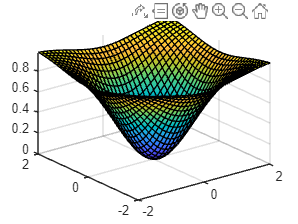

x = sym('x');
y = sym('y');
cov = sym('c',[2,2]);
cov = [1,0;0,1];
pro_g = matlabFunction(sym((1-exp(-1/2*[x;y]'*inv(cov)*[x;y]))));
fsurf(pro_g,[-2 2 -2 2])

dist_rev=sym((1-exp(-1/2*[x;y]'*inv(cov)*[x;y])))

$$dist\_rev = 1-{\mathrm{e}}^{-\frac{x\,\bar{x}}{2}-\frac{y\,\bar{y}}{2}}$$

f_mass = int(dist_rev,x)

$$f\_mass = x-\frac{\sqrt{2}\,\sqrt{\pi }\,{\mathrm{e}}^{-\frac{y\,\bar{y}}{2}}\,\mathrm{erf}\left(\frac{\sqrt{2}\,x}{2}\right)}{2}$$

f_cent=int(x*dist_rev,x)

$$f\_cent = {\mathrm{e}}^{-\frac{x^{2}}{2}-\frac{y\,\bar{y}}{2}}+\frac{x^{2}}{2}$$

line_int(polyg,@(x,y) 0*x,matlabFunction(f_cent))/line_int(polyg,@(x,y) 0*x, matlabFunction(f_mass))

ans = 41.1211

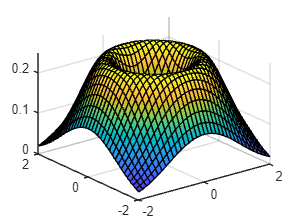

fsurf(matlabFunction(dist_rev*(-sym(pro_g)+1)),[-2 2 -2 2])

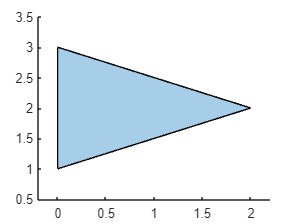

a=[0,2,0];
b = [1,2,3];
c = polyshape(a,b);
plot(c)

plot(polyshape(bots(1).obst(1,:),bots(1).obst(2,:)))

Index in position 1 exceeds array bounds.

figure 
hold on
plot(bots(3).obst(1,:),bots(3).obst(2,:))
plot(bots(3).verts(1,:),bots(3).verts(2,:))


a = intersect(polyshape(bots(3).verts(1,:),bots(3).verts(2,:)),polyshape(bots(3).obst(1,:),bots(3).obst(2,:)))

